frame synchronisation with random bit signal

% rep encoded
rep_bits = repencode(source(100, 0.4), 3);

% pre- and post- amble as well as noise
noise = source(20, 0.5);

% cross correlation should grow exponentially with length of preamble,
% assuming gaussian generating process!
code = [1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 1];
transmitted_bits = [noise code rep_bits ~code noise];

cross correlation needs 0s and 1s to work

function xcorr_bits = def(b)
xcorr_bits = (b.*2) - 1;
end

compute cross correlation for pre and postamble

[phi, tau] = xcorr(def(transmitted_bits), def(code));

% truncate negative shift values
phi = phi(length(transmitted_bits):end);
tau = tau(length(transmitted_bits):end);


look at first index where cross-correlation is maximal

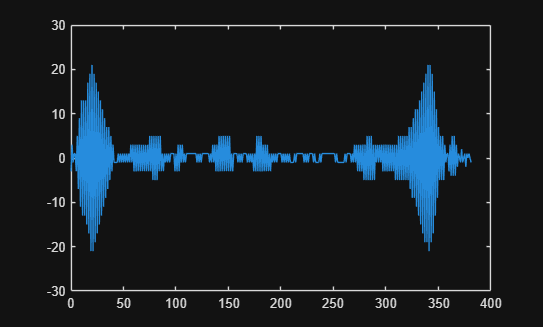


plot(tau, phi)


[max_value, idx] = max(phi)

max_value = 21

idx = 21


transmitted_bits(idx:idx+length(code)-1) 

ans =      1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1


% this should equal the preamble, idx should be 21 because of 20 bits of
% noise

truncate the noisy part before and after the found index

trunc_bits = transmitted_bits(idx+length(code):end);

testing framesync function

synced_bits = framesync(transmitted_bits, code, ~code);

calcBER(rep_bits, synced_bits)

ans = 0